syms x y

% Exercise 2
fx = -x + 0.08*y +x^2*y

$$fx = y\,x^{2}-x+\frac{2\,y}{25}$$

fy = 0.6 - 0.08*y -x^2*y

$$fy = -y\,x^{2}-\frac{2\,y}{25}+\frac{3}{5}$$

% setting the matlab function for our system
f_lmb = @(t,z) [-z(1) + 0.08*z(2) + (z(1))^2 * z(2);0.6 - 0.08*z(2) - (z(1)^2) * z(2)];

% 1. CALCULATE THE FIXED POINTS
fixPts = solve([fx; fy], [x; y])

fixPts = struct with fields:
    x: 3/5
    y: 15/11


fixPts = double([fixPts.x'; fixPts.y'])

fixPts =     0.6000
    1.3636



% Computing the jacobian matrix and the eigenvalues for the fixed points
JacFixPts = zeros(2, 2, size(fixPts, 2));
eigenvalues = zeros(size(fixPts, 2), 2);

for k = 1:size(fixPts, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx, fy], [x, y]), {x, y}, {fixPts(1, k), fixPts(2, k)}));
    eigenvalues(k, :) = eig(JacFixPts(:,:,k));
end

% 2. IDENTIFY AND CLASSIFY THE FIXED POINTS: HYPERBOLIC VS NON-HYPERBOLIC
for k =1:size(fixPts, 2)
    if all(real(eigenvalues(k, :)) ~= 0)
        fprintf('Fixed point at (%f, %f) is hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    else
        fprintf('Fixed point at (%f, %f) is not hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    end
end

Fixed point at (0.600000, 1.363636) is hyperbolic.



% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts(1,:), fixPts(2,:), 'o', 'MarkerFaceColor', 'r');


% 3. COMPUTE THE NULLCLINES
% with respect y
xcline_y = solve(fx == 0, y);
ycline_y = solve(fy == 0, y);


xcline_y = solve(fx == 0, y);
ycline_y = solve(fy == 0, y);

% Calcula las derivadas
derivada_xcline_y = diff(xcline_y, x);
derivada_ycline_y = diff(ycline_y, x);

% Calcula el rango de 10 valores de x de 0 a 5
rango_x = linspace(0, 5, 25);

% Inicializa matrices para almacenar los valores y las derivadas
valores_xcline_y = zeros(size(rango_x));
valores_ycline_y = zeros(size(rango_x));
derivadas_xcline_y = zeros(size(rango_x));
derivadas_ycline_y = zeros(size(rango_x));

% Evalúa las funciones y calcula las derivadas en el rango
for i = 1:length(rango_x)
    valores_xcline_y(i) = subs(xcline_y, x, rango_x(i));
    valores_ycline_y(i) = subs(ycline_y, x, rango_x(i));
    
    % Evalúa las derivadas en el punto actual del rango
    derivadas_xcline_y(i) = subs(derivada_xcline_y, x, rango_x(i));
    derivadas_ycline_y(i) = subs(derivada_ycline_y, x, rango_x(i));
end

% Normaliza los vectores de flujo (derivadas)
magnitudes = sqrt(derivadas_xcline_y.^2 + derivadas_ycline_y.^2);
derivadas_xcline_y = derivadas_xcline_y ./ magnitudes;
derivadas_ycline_y = derivadas_ycline_y ./ magnitudes;

quiver(rango_x, valores_xcline_y, zeros(size(rango_x)), derivadas_xcline_y, 'Color', 'm', 'AutoScale', 'on', 'AutoScaleFactor', 0.5);
quiver(rango_x, valores_ycline_y, derivadas_ycline_y, zeros(size(rango_x)), 'Color', 'm', 'AutoScale', 'on', 'AutoScaleFactor', 0.5);

% Representing the nullclines

nullX = fimplicit(fx, [-eps 5 -eps 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy, [-eps 5 -eps 5], 'g--', 'LineWidth', 1.5);

% 5. REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(0, 5, N);
ylin = linspace(0, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

axis([-eps 3.5 -eps 3.5]);
xlabel('x');
ylabel('y');
title('Campo vectorial con puntos fijos, eigenvalores y nullclines');

% REPRESENT AN  UPWARD RADIUS PATH
y0 = [0.5 2]

y0 =     0.5000    2.0000


t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% REPRESENT A DOWNWARD RADIUS PATH
y0 = [3 2]

y0 =      3     2


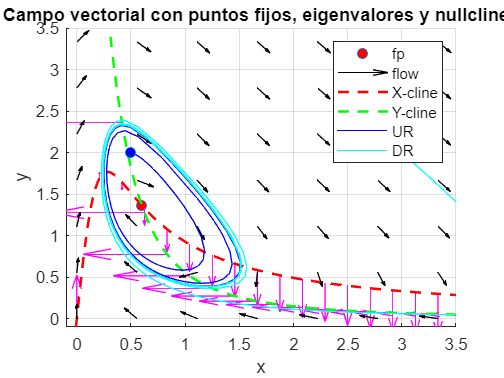

t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj2 = plot(ys(:,1),ys(:,2),'cyan-'); plot(y0(1),y0(2),'o','MarkerFaceColor','cyan');

legend([fpts flow nullX nullY traj1 traj2],{'fp', 'flow', 'X-cline', 'Y-cline', 'UR', 'DR'},'Location', 'NorthEast')


disp('As it can be seen in the phase diagram, this system has a limit cycle')

As it can be seen in the phase diagram, this system has a limit cycle
